# Radar Specifications

%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

frequency = 77e9;
c = 3e8;
max_range = 200;
range_resolution = 1;
max_velocity = 100;

## User Defined Range and Velocity of target

The initial target is set up at 30m range with a velocity of 10m/s.

position = 30;
velocity = 10;

## FMCW Waveform Generation

% *%TODO* :
% Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.
B = c / (2*range_resolution);
Tchirp = 5.5 * 2 * max_range / c;
slope = B / Tchirp;
                                                          
%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples

%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
r_t=zeros(1,length(t));
td=zeros(1,length(t));

With the given specifications Bandwidth (B), chirp time (Tchirp) and slope can be calculated:

B = 150000000

Tchrip = 7.33e-06

slope = 2.045e+13

## Signal generation and Moving Target simulation

Given the position and velocity n timesteps for the radar measurements can be calculated with mixing transmitting and receiving signals.

for i=1:length(t)         
    
    
    % *%TODO* :
    %For each time stamp update the Range of the Target for constant velocity. 
    r_t(i) = position + velocity * t(i);
    td(i) = 2 * r_t(i) / c;
    
    % *%TODO* :
    %For each time sample we need update the transmitted and
    %received signal. 
    Tx(i) = cos(2 * pi * (fc * t(i) + slope * t(i)^2 / 2));
    Rx(i) = cos(2 * pi * (fc * (t(i) - td(i)) + (slope * (t(i) - td(i))^2) / 2));
    
    % *%TODO* :
    %Now by mixing the Transmit and Receive generate the beat signal
    %This is done by element wise matrix multiplication of Transmit and
    %Receiver Signal
    Mix(i) = Tx(i) * Rx(i);
end

## RANGE MEASUREMENT

After obtaining all time step measurements we can use Fast Fourier Transform and plot the range measurement of the signal.

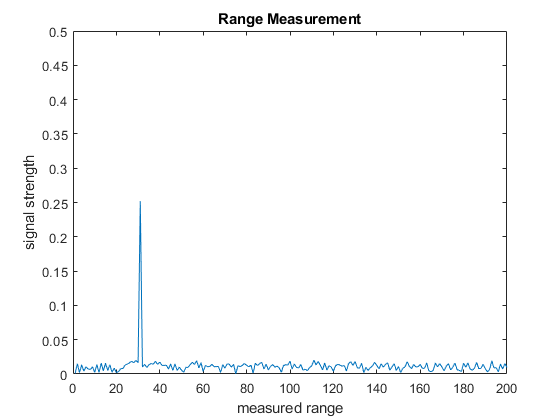

 % *%TODO* :
%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
sig_fft = reshape(Mix, [1, (Nr * Nd)]);

 % *%TODO* :
%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.
sig_fft = fft(sig_fft, Nr)./Nr;


 % *%TODO* :
% Take the absolute value of FFT output
sig_fft = abs(sig_fft);

 % *%TODO* :
% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
sig_fft = sig_fft(1:(Nr/2-1));

%plotting the range
figure ('Name','Range from First FFT')
%subplot(2,1,1)
plot(sig_fft);
axis([0 200 0 0.5]);
xlabel('measured range');
ylabel('signal strength');
title('Range Measurement');

## RANGE DOPPLER RESPONSE

Similar to 1D Fast Fourier Transform on range, this can now be done with a 2D representation of the observation with range and velocity measurements.

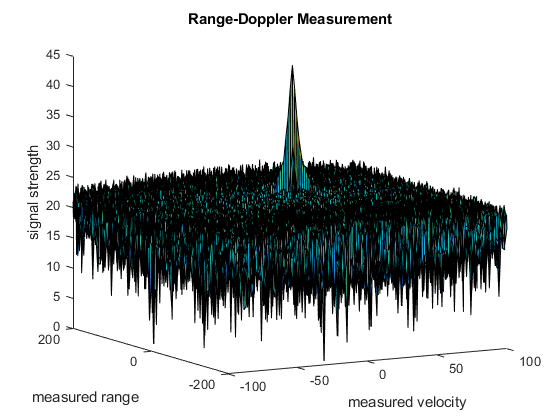

% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);

xlim([-100 100])
ylim([-200 200])
zlim([0 45])
view([-29.1 10.8])
xlabel('measured velocity');
ylabel('measured range');
zlabel('signal strength');
title('Range-Doppler Measurement');
grid off;

## CFAR implementation

Finally by applying 2D CFAR thresholding on each observation, a finite range and velocity of the target object can be made. Tunable parameters:

Training Cells Range: 30

Training Cells Doppler: 8

Guard Cells Range: 8

Guard Cells Doppler: 3

Offset= 10

The range of training cells was specifically a little bit wider than in the explanations because I noticed that smaller ranges will also surpress the signal below the threshold. Unfortunatly this also means a brief cut in performance, since every increase of the range has an exponentially larger calculation time. One way to overcome this is to increase the number of guard cells so the signal can still be clearly above further away training cells. Amount of Doppler cells are smaller because the scale is also much smaller than the range dimension. 

For Offset I chose 10 because as can be seen in previous graph the signal pops out about 20 higher than the average noise. Therefore 10 should be a sufficient offset on top to identify signal from noise.

For CFAR thresholding I iterate over every observation within the 512*128 RDM array, substracting the cutoff range of training and guard cells respectively. Then for each CUT (Cell under Test) the average of all training cells plus provided offset is used as local threshold for that specific CUT. If array value is greater than calculated number, then a correct measurement in this spot in 2D-Range-Doppler map is likely. Finally the outer edges of the observation spectrum need to be cut. In my implementation I chose the naive approach and just checked every value in array if its greater than 1 and put it to 0.

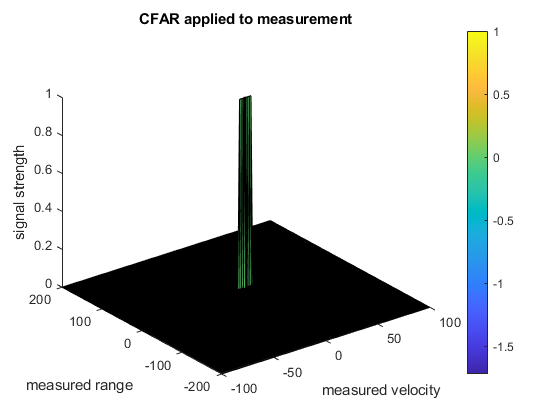

%Slide Window through the complete Range Doppler Map

% *%TODO* :
%Select the number of Training Cells in both the dimensions.
Tr = 30;
Td = 8;

% *%TODO* :
%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation
Gr = 8;
Gd = 3;

% *%TODO* :
% offset the threshold by SNR value in dB
offset = 10;

% *%TODO* :
%Create a vector to store noise_level for each iteration on training cells
noise_level = zeros(1,1);
grid_size = (2*Tr + 2*Gr+1) * (2*Td + 2*Gd + 1);
training_cells = grid_size - (2*Gr+1) * (2*Gd+1);

CFAR_sig = zeros(size(RDM));


% *%TODO* :
%design a loop such that it slides the CUT across range doppler map by
%giving margins at the edges for Training and Guard Cells.
%For every iteration sum the signal level within all the training
%cells. To sum convert the value from logarithmic to linear using db2pow
%function. Average the summed values for all of the training
%cells used. After averaging convert it back to logarithimic using pow2db.
%Further add the offset to it to determine the threshold. Next, compare the
%signal under CUT with this threshold. If the CUT level > threshold assign
%it a value of 1, else equate it to 0.


   % Use RDM[x,y] as the matrix from the output of 2D FFT for implementing
   % CFAR
cutoff_range = Tr + Gr;
cutoff_doppler = Td + Gd;

for r = 1 + cutoff_range:Nr/2 - cutoff_range
    for d = cutoff_doppler + 1: Nd - cutoff_doppler
        
        for i = r - cutoff_range : r + cutoff_range
            for j = d - cutoff_doppler : d + cutoff_doppler
                % filter only training cells
                if (abs(r-i) > Gr || abs (d-j) > Gd)
                    noise_level = noise_level + db2pow(RDM(i,j));
                end
            end
        end
        
        local_threshold = pow2db(noise_level / training_cells);
        local_threshold = local_threshold + offset;
        CUT = RDM(r,d);
        
        if (CUT < local_threshold)
            RDM(r,d) = 0;
        else
            RDM(r,d) = 1;
        end
        
        noise_level = zeros(1,1);
        
    end
end



% The process above will generate a thresholded block, which is smaller 
%than the Range Doppler Map as the CUT cannot be located at the edges of
%matrix. Hence,few cells will not be thresholded. To keep the map size same
% set those values to 0. 

for i = 1 : Nr/2
    for j = 1:Nd
        if (RDM(i,j) > 1)
             RDM(i,j) = 0;
        end
    end
end



% *%TODO* :
%display the CFAR output using the Surf function like we did for Range
%Doppler Response output.
figure,surf(doppler_axis,range_axis,RDM);
colorbar;
xlim([-100 100])
ylim([-200 200])
zlim([0 1])
xlabel('measured velocity');
ylabel('measured range');
zlabel('signal strength');
title('CFAR applied to measurement');
grid off;